clear all
clc

PRI = 1.2;  % s - Pulse repreat interval
Tp  = 1e-1;  % s - Pulse duration
fs = 1e3;  % 1 kHz - Sampling frequency
dt = 1/fs;

t   = (0:dt:PRI-dt);  % s

% Transmit signal
A   = 5;  % V
fc  = 100;  % 100 Hz
sTx = A * rectangularPulse(0, 1, t/Tp) .* cos(2*pi*fc*t);

% Say the target causes a roundtrip delay of tau = 0.7 s < PRI = 1 s. Also,
delay = 0.7;  % s
reflectivity = 0.5;

% received signal w/o noise
% Question: Does tau affect the harmonic term?
sRx = reflectivity * A * rectangularPulse(0, 1, (t-delay)/Tp) .* cos(2*pi*fc*(t-delay));

% received signal w/ gaussian white noise. 
SNR_set = 0.2;
sRxwNoise = awgn(sRx, SNR_set);

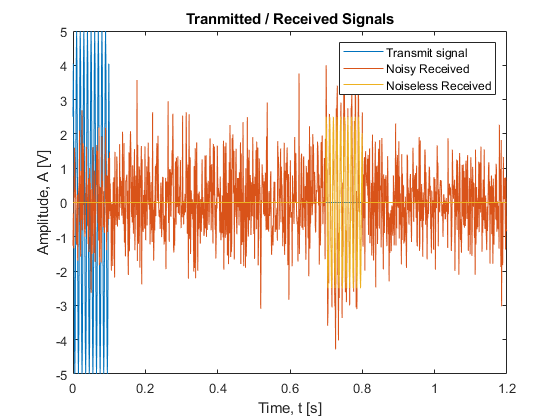

% Matched Filter - Time Domain Cross-correlation
[m, lags] = xcorr(sRxwNoise, sTx);
m = m(lags >= 0);
lg = lags(lags >= 0);

figure
plot(t, sTx, t, sRxwNoise, t, sRx);
xlabel("Time, t [s]");
ylabel("Amplitude, A [V]");
title("Tranmitted / Received Signals");
legend("Transmit signal", "Noisy Received", "Noiseless Received");

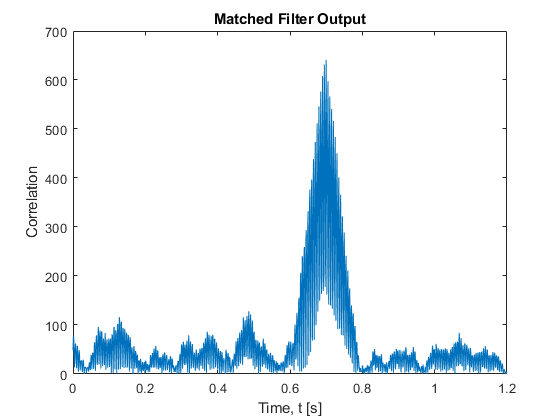


figure
plot(t, abs(m));
xlabel("Time, t [s]");
ylabel("Correlation");
title("Matched Filter Output");

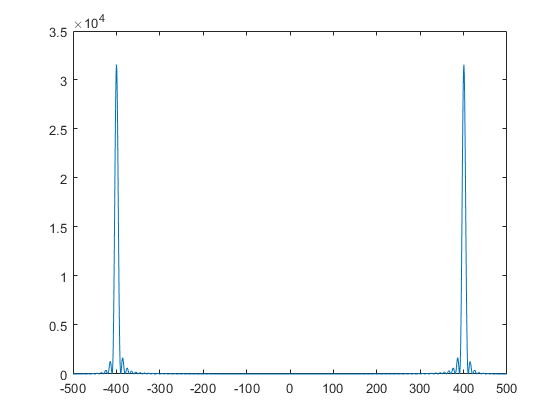

% Matched Filtering - Frequency Domain implementation of cross-correlation
% Refer: https://en.wikipedia.org/wiki/Cross-correlation
% Refer: https://en.wikipedia.org/wiki/Convolution
% Time Domain                       |   Frequeny Domain
% _____________                         _______________
% convolution: use flipped signal   | product
% correlation                       | product: use flipped conjugate of
% signal

X = fft(sRx);
y = fliplr(sTx);
Y = conj(fft(y));

assert(length(X)==length(Y));
M = X.*Y;
f = linspace(-fs/2, fs/2, length(M));

figure
plot(f, abs(M))